# Covariates in regression analyses

This script simulates some common situations related to linear regression and explores power and effects.

Notation: 

**e** = error variable, simulates measurement error that cannot be explained by any predictor

**xs, ys, cs: *s "signal **variables" indicate latent variables of theoretical interest (without measurement noise). These are never directly observable

**x, y, c:** single-letter variables are measured variables. These are the observed variables that one can measure and include in regression models. ingle-letter variables 

-> indicates a causal effect

Variables with no *e are noiseless.

### Controlling for an outcome-unrelated covariate

Here, xs is a mediator of cs -> y, and controlling for c weakens the xs -> y relationship

Simplified model (assuming all measured variables have measurement error, so omitting *e:

c is related only to x.  x is related only to y.

%  x -> y 
%  ^
%  |
%  c
%

Underlying model:

% xe                ye
%  |                |
%  v                v
%  x <- xs -> ys -> y
%       ^
%       |
%  c <- cs
%  ^
%  |
%  ce
%

% true
n = 1000;
clear d      % effect sizes
iter = 100;

for i = 1:iter
    
    % error
    ye = randn(n, 1); % y error
    xe = randn(n, 1); % x error
    ce = randn(n, 1); % c error
    
    % true causal signals
    cs = randn(n, 1);              % c true signal
    xs = randn(n, 1) + cs;  % x true signal (c contributes)
    ys = randn(n, 1) + xs;  % y true signal (c, x contribute)
   
    % observed signals: plus random noise (e)
    y = (ys + ye); % y observed (c does not contribute)
    x = (xs + xe); % x observed
    c = (cs + ce);
    
    % Fit with c
    [betas, dev, stats] = glmfit([x c], y);
    if i < 2, glm_table(stats, {'x' 'c'}); end
    tval = stats.t(2);
    d(i, 1) = tval ./ sqrt(n);
    
    % Fit without c
    [betas, dev, stats] = glmfit(x, y);
    if i < 2, glm_table(stats, {'x'}); end
    tval = stats.t(2);
    d(i, 2) = tval ./ sqrt(n);
    
end

        Name           Beta         SE          t           p           Sig  
    _____________    ________    ________    _______    __________    _______

    {'Intercept'}    -0.06267    0.049591    -1.2637       0.20662    {' '  }
    {'x'        }      0.5651    0.031491     17.944    1.3005e-62    {'***'}
    {'c'        }     0.20091    0.038327     5.2419    1.9401e-07    {'***'}



        Name           Beta          SE          t           p          Sig  
    _____________    _________    ________    _______    _________    _______

    {'Intercept'}    -0.058665    0.050238    -1.1677      0.24319    {' '  }
    {'x'        }      0.63326    0.029059     21.792    1.968e-86    {'***'}



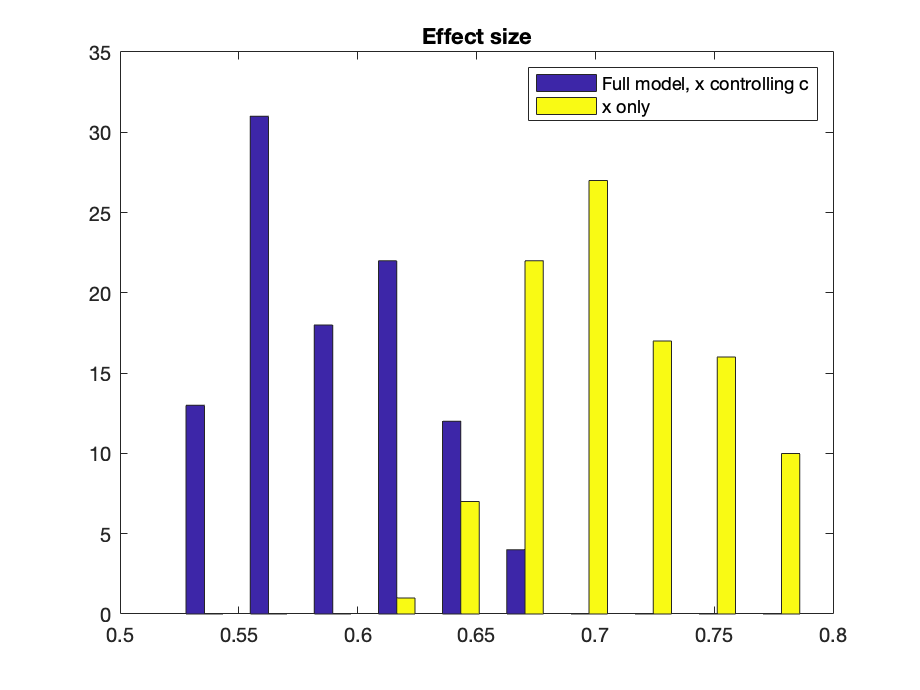


figure; hist(d); legend({'Full model, x controlling c', 'x only'}); title('Effect size')

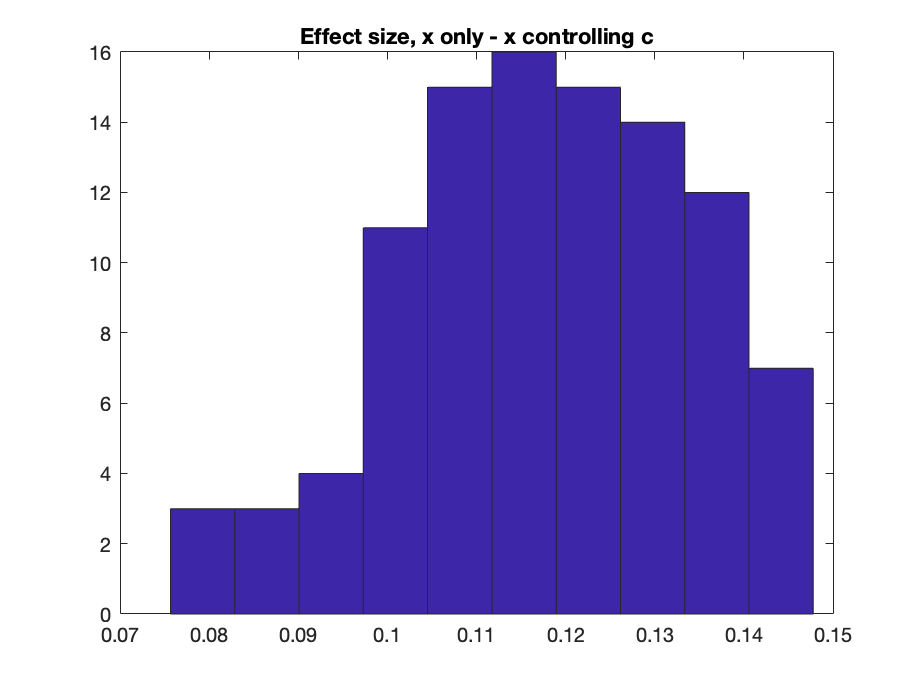

figure; hist(d(:, 2) - d(:, 1)); title('Effect size, x only - x controlling c');

### Controlling for an outcome-unrelated covariate, take 2

Here, xs is a mediator of cs -> y, and controlling for c weakens the xs -> y relationship

Simplified model (assuming all measured variables have measurement error, so omitting *e:

c is related only to x.  x is related only to y.

%     b
%   x -> y 
%   ^
% a |
%   c
%

% true
n = 1000;
clear d      % effect sizes
iter = 100;

a = 1;
b = 1;
sigma = 1;

for i = 1:iter
    
    % error
    ye = sigma .* randn(n, 1); % y error
    xe = sigma .* randn(n, 1); % x error
    ce = sigma .* randn(n, 1); % c error
    
    % true causal signals
    cs = randn(n, 1);              % c true signal
    xs = a .* cs;  % x true signal (c contributes)
    ys = b .* xs;  % y true signal (c, x contribute)
   
    % observed signals: plus random noise (e)
    y = (ys + ye); % y observed (c does not contribute)
    x = (xs + xe); % x observed
    c = (cs + ce);
    
    % Fit with c
    [betas, dev, stats] = glmfit([x c], y);
    if i < 2, glm_table(stats, {'x' 'c'}); end
    tval = stats.t(2);
    d(i, 1) = tval ./ sqrt(n);
    
    % Fit without c
    [betas, dev, stats] = glmfit(x, y);
    if i < 2, glm_table(stats, {'x'}); end
    tval = stats.t(2);
    d(i, 2) = tval ./ sqrt(n);
    
end

        Name           Beta          SE          t           p           Sig  
    _____________    _________    ________    _______    __________    _______

    {'Intercept'}    -0.036127    0.034985    -1.0326       0.30202    {' '  }
    {'x'        }      0.33484     0.02908     11.514    6.8331e-29    {'***'}
    {'c'        }      0.34515    0.028681     12.034    3.0499e-31    {'***'}



        Name           Beta          SE          t            p           Sig  
    _____________    _________    ________    ________    __________    _______

    {'Intercept'}    -0.029648    0.037417    -0.79236       0.42834    {' '  }
    {'x'        }      0.51371    0.026735      19.215    2.9429e-70    {'***'}




r = corr([c x y])

r =     1.0000    0.4826    0.4681
    0.4826    1.0000    0.4682
    0.4681    0.4682    1.0000


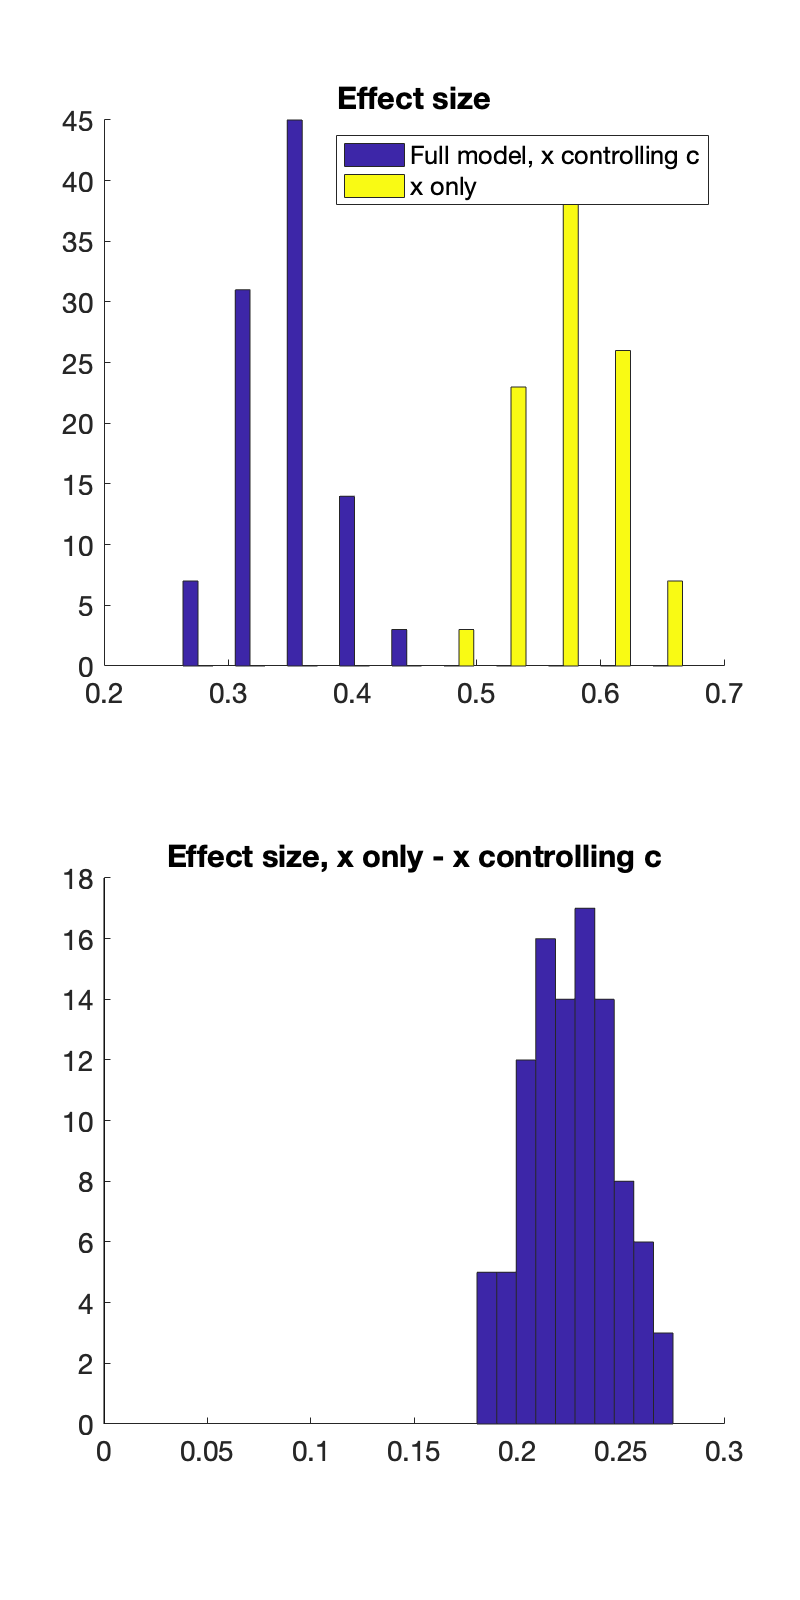

ans =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0]
              YData: [0 18]
              ZData: [1×0 double]

  Show all properties



create_figure('histograms', 2, 1); 
hist(d); legend({'Full model, x controlling c', 'x only'}); title('Effect size')

subplot(2, 1, 2)
hist(d(:, 2) - d(:, 1)); title('Effect size, x only - x controlling c');
plot_vertical_line(0);

disp('Pos = worse to control for c; Neg = better to control for c')

Pos = worse to control for c; Neg = better to control for c


## Controlling on an outcome-unrelated covariate

causal connections:

xe | v x [xs -](http://-) y [ye ^ | cs -](http://-) c ^ | ce

%     b
%   x -> y 
%   ^
% a |
%   c
%

% xe
%  |
%  v
%  x <- xs -> ys -> y <- ye
%  ^
%  |
%  cs -> c
%        ^
%        |
%        ce

Here, cs and xs are unrelated and c contributes a source of error to observed x.

 Controlling for c strengthens the xs -> y relationship.

 x is a "pseudo-mediator" here, because the cs->x effect and xs->y effects are actually independent.

c is not related to y, but appears to be a suppressor (significant negative relationship with y).

% true
n = 1000;
clear d      % effect sizes
iter = 100;

a = .01;
b = 1;
sigma = 1;

for i = 1:iter
    
    ye = sigma .* randn(n, 1); % y error
    xe = sigma .* randn(n, 1); % x error
    ce = sigma .* randn(n, 1); % c error
    
    cs = randn(n, 1);            % c true signal
    xs = randn(n, 1);            % x true signal (c does not contribute)
    ys = b .* xs;
    
    % observed signals: plus random noise (e)
    y = ys + ye;                    % y observed (c does not contribute)
    x = (xs + xe + a .* cs); % x observed
    c = cs + ce;
    
    % Fit with c
    [betas, dev, stats] = glmfit([x c], y);
    if i < 2, glm_table(stats, {'x' 'c'}); end
    tval = stats.t(2);
    d(i, 1) = tval ./ sqrt(n);
    
    % Fit without c
    [betas, dev, stats] = glmfit(x, y);
    if i < 2, glm_table(stats, {'x'}); end
    tval = stats.t(2);
    d(i, 2) = tval ./ sqrt(n);
    
    e = ys - x * betas(2); % prediction error (residuals)
    1 - (var(e) ./ var(ys)); % prediction r^2 var explained;

end

        Name           Beta          SE           t            p           Sig  
    _____________    _________    ________    _________    __________    _______

    {'Intercept'}    -0.037737    0.038439     -0.98173       0.32647    {' '  }
    {'x'        }      0.52443    0.027417       19.128    1.0201e-69    {'***'}
    {'c'        }    -0.001306    0.027737    -0.047085       0.96246    {' '  }



        Name           Beta          SE          t            p           Sig  
    _____________    _________    ________    ________    __________    _______

    {'Intercept'}    -0.037819    0.038381    -0.98534       0.32469    {' '  }
    {'x'        }      0.52447    0.027393      19.146    7.7411e-70    {'***'}




r = corr([c x y])

r =     1.0000    0.0126    0.0713
    0.0126    1.0000    0.4896
    0.0713    0.4896    1.0000


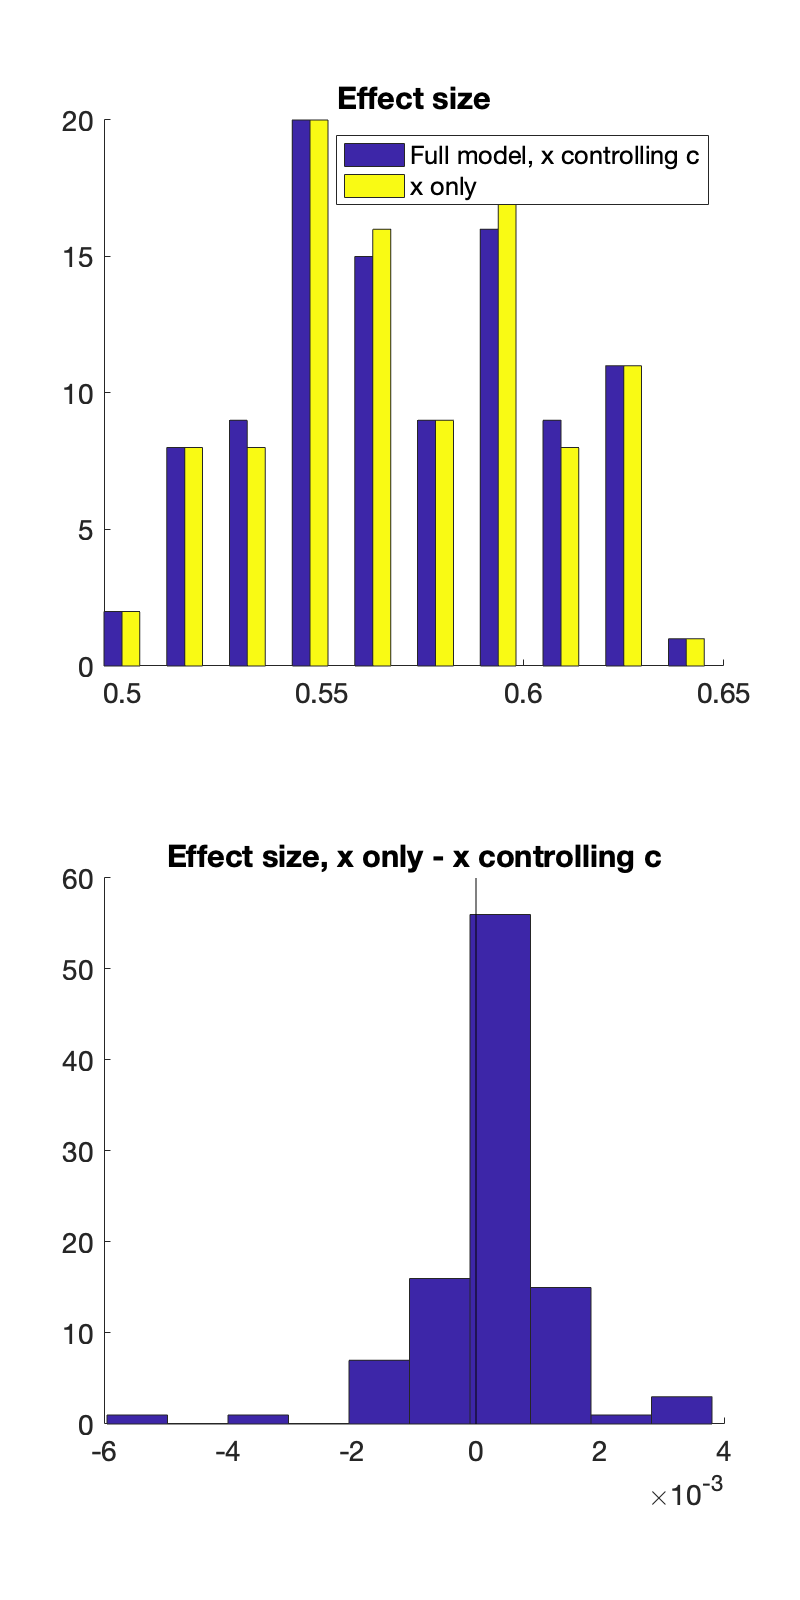


create_figure('histograms', 2, 1); 
hist(d); legend({'Full model, x controlling c', 'x only'}); title('Effect size')

subplot(2, 1, 2)
hist(d(:, 2) - d(:, 1)); title('Effect size, x only - x controlling c');
plot_vertical_line(0);

disp('Pos = worse to control for c; Neg = better to control for c')

Pos = worse to control for c; Neg = better to control for c


causal connections:

## Conditioning on a collider

% c < y
% ^
% x

% true
n = 1000;

x = randn(n, 1);
y = randn(n, 1);
c = (x + y + randn(n, 1)) ./ 3;
int = ones(size(x));

[betas,~, r, ~, stats] = regress(y, [int c x]);

create_figure('scatter', 2, 2)

% All
plot(x, y, 'ko', 'MarkerFaceColor', [.5 .5 .5]);
xlabel('x - Income')
ylabel('y - IQ')
title('All observations')
refline

wh = c > median(c);

% Split - together
subplot(2, 2, 2)
% plot(x, y, 'ko', 'MarkerFaceColor', [.5 .5 .5]);
plot(x(wh), y(wh), 'ko', 'MarkerFaceColor', [.7 .3 .8]);
plot(x(~wh), y(~wh), 'ko', 'MarkerFaceColor', [.2 .7 .5]);
xlabel('x - Income')
ylabel('y - IQ')
title('Conditioning on c (school quality)')
refline

subplot(2, 2, 3)

plot(x(wh), y(wh), 'ko', 'MarkerFaceColor', [.7 .3 .8]);
refline
plot(x(~wh), y(~wh), 'ko', 'Color', [.7 .7 .7]);

xlabel('x - Income')
ylabel('y - IQ')

title('High c (good schools)')


subplot(2, 2, 4)

plot(x(~wh), y(~wh), 'ko', 'MarkerFaceColor', [.2 .7 .5]);
refline
plot(x(wh), y(wh), 'ko', 'Color', [.7 .7 .7]);

xlabel('x - Income')
ylabel('y - IQ')

title('Low c (poor schools)')

## Conditioning on a common cause

% c > y
% v
% x

% true
n = 1000;

c = randn(n, 1);
x = (randn(n, 1) + c) ./ 2;
y = (randn(n, 1) + c) ./ 2;
% c = (x + y + randn(n, 1)) ./ 3;
int = ones(size(x));

[betas,~, r, ~, stats] = regress(y, [int c x]);

create_figure('scatter', 2, 2)

% All
plot(x, y, 'ko', 'MarkerFaceColor', [.5 .5 .5]);
xlabel('x - Income')
ylabel('y - IQ')
title('All observations')
refline

wh = c > median(c);

% Split - together
subplot(2, 2, 2)
% plot(x, y, 'ko', 'MarkerFaceColor', [.5 .5 .5]);
plot(x(wh), y(wh), 'ko', 'MarkerFaceColor', [.7 .3 .8]);
plot(x(~wh), y(~wh), 'ko', 'MarkerFaceColor', [.2 .7 .5]);
xlabel('x - Income')
ylabel('y - IQ')
title('Conditioning on c (school quality)')
refline

subplot(2, 2, 3)

plot(x(wh), y(wh), 'ko', 'MarkerFaceColor', [.7 .3 .8]);
refline
plot(x(~wh), y(~wh), 'ko', 'Color', [.7 .7 .7]);

xlabel('x - Income')
ylabel('y - IQ')

title('High c (good schools)')


subplot(2, 2, 4)

plot(x(~wh), y(~wh), 'ko', 'MarkerFaceColor', [.2 .7 .5]);
refline
plot(x(wh), y(wh), 'ko', 'Color', [.7 .7 .7]);

xlabel('x - Income')
ylabel('y - IQ')

title('Low c (poor schools)')